In this file, we compare the three ways of implementing the algorithms:

- accumulated_reward_numit.m. Only non-zeros elements were considered in the calculation. Also,  truncation by aggregation is considered.

- accumulated_reward_numit_direct.m. All the elements, not just the non zeros are considered in the calculation. Also, no truncation is considered.

- accumulated_reward_numit_ext_markov.m. Construct an extended markov chain and use matrix multiplication for the calculation.

Two use cases are used:

- the use case in subfolder trials_use_case_1.

- the use case taken from our RESS paper.

## Use case 1.

We create the same use case as before:

clear; clc;
%% Parameter definition
S = 1:5; % state space
pi = [1,0,0,0,0]; % initial distribution
% Define the Q-matrix
Q = [0,.1,.5,.25,0;...
    1,0,.5,0,.5;...
    0,.25,0,1,.5;...
    1,0,0,0,.5;...
    1,.25,0,1,0];
for i = 1:5
    Q(i,i) = -1*sum(Q(i,:));
end
r = [5,2,4,5,4]; % Reward matrix
x_max = 110; % Limit x values
T_max = 25; % Time limit

Here we make a simple transformation to make sure the smallest reward is $0.$ This can be done by simply let $r=r-min(r).$ Also, the same tranformation has to be considered in the threshold for the accumulated reward. This can save computational efforts as for $r=0,$ no reward is accumulated. Thus, less computation is needed.

offset = -2;
r = r+offset;
x_max = x_max + offset*T_max;
% Defining the structure para
para.S = S;
para.pi = pi;
para.Q = Q;
para.r = r;

We run the test for the three algorithms. The rows in the result and elasped_time corresponds to accumulated_reward_numit, accumulated_reward_numit_direct and accumulated_reward_numit_ext_markov, respectively.

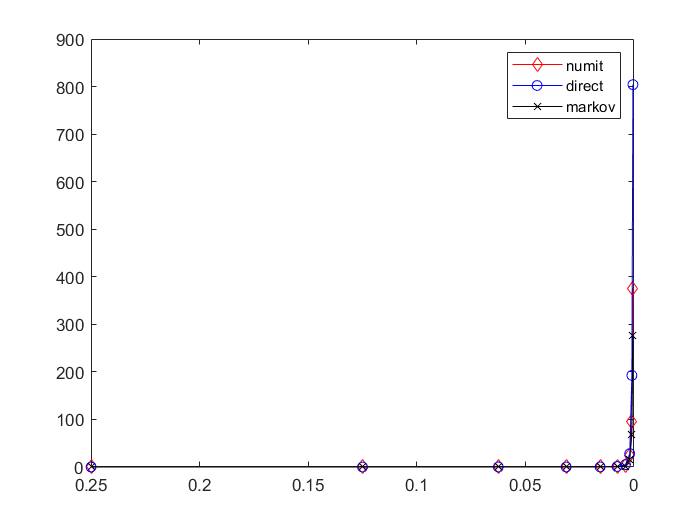

% Delta = 1/4*(1/2).^(0:9);
% result = zeros(3,length(Delta));
% elasped_time = zeros(3,length(Delta));
% % Run the test.
% for i = 1:length(Delta)
%     % First method.
%     tic;
%     result(1,i) = 1 - accumulated_reward_numit(T_max,x_max,Delta(i),para);
%     elasped_time(1,i) = toc;
%     % Second method.
%     tic;
%     result(2,i) = 1 - accumulated_reward_numit_direct(T_max,x_max,Delta(i),para);
%     elasped_time(2,i) = toc;
%     % Third method.
%     tic;
%     result(3,i) = 1 - accumulated_reward_numit_ext_markov(T_max,x_max,Delta(i),para);
%     elasped_time(3,i) = toc;
%     % Output the results.
%     fprintf('%d/%d\n',i,length(Delta));
%     fprintf('Delta = %f\n',Delta(i));
%     disp(result(:,i));
%     disp(elasped_time(:,i));
% end
% save('result_use_case-1')
load('result_use_case-1')
% Visualize the computation time.
figure
plot(Delta,elasped_time(1,:),'r-d',...
    Delta,elasped_time(2,:),'b-o',...
    Delta,elasped_time(3,:),'k-x');
set(gca,'Xdir','reverse');
legend('numit','direct','markov')

### Finding

Markov approach is also better. Up to point 7, numit is slower than direct. But from point 8, numit is faster than direct.

## Use case 2.

We consider a second use case which is from our paper that is submitted to RESS. The difficult part in this use case is that the repair rate is much larger than failure rate, so to ensure only one event occurs in the interval, $\Delta$ needs to be extremely small.

clear; clc;
%% Parameter definition
S = 1:5; % state space
pi = [1,0,0,0,0]; % initial distribution
% Define the Q-matrix
Q = [0, 1.2298e-4, 1.2298e-4, 2.5939e-4, 3.0095e-4;...
    .76, 0, 0, 0, 0;...
    .76, 0, 0, 0, 0;...
    0, .76, 0, 0, 0;...
    0, 0, 0, 0, 0];
r = [0, 7.24, 18.2, 25.4, 25.4]*100/4; % Reward matrix
offset = 0;
r = r+offset;
for i = 1:5
    Q(i,i) = -1*sum(Q(i,:));
end
% Defining the structure para
para.S = S;
para.pi = pi;
para.Q = Q;
para.r = r;
x_max = 25.4*100/4; % Limit x values
T_max = 40; % Time limit
x_max = x_max+offset*T_max;

We run the test for the three algorithms. The rows in the result and elasped_time corresponds to accumulated_reward_numit, accumulated_reward_numit_direct and accumulated_reward_numit_ext_markov, respectively.

% Delta = 1/4*(1/2).^(0:7);
% result_case_2 = zeros(3,length(Delta));
% elasped_time_case_2 = zeros(3,length(Delta));
% % Run the test.
% for i = 1:length(Delta)
%     % First method.
%     tic;
%     result_case_2(1,i) = 1 - accumulated_reward_numit(T_max,x_max,Delta(i),para);
%     elasped_time_case_2(1,i) = toc;
%     % Second method.
%     tic;
%     result_case_2(2,i) = 1 - accumulated_reward_numit_direct(T_max,x_max,Delta(i),para);
%     elasped_time_case_2(2,i) = toc;
%     % Third method.
%     tic;
%     result_case_2(3,i) = 1 - accumulated_reward_numit_ext_markov(T_max,x_max,Delta(i),para);
%     elasped_time_case_2(3,i) = toc;
%     % Output the results.
%     fprintf('%d/%d\n',i,length(Delta));
%     fprintf('Delta = %f\n',Delta(i));
%     disp(result_case_2(:,i));
%     disp(elasped_time_case_2(:,i));
% end
% save('result_use_case-2');

1/8


Delta = 0.250000


     1.998460500859145e-02
     1.998460500859134e-02
     1.998460500859067e-02



     2.462440000000000e-02
     2.033530000000000e-02
     8.704600000000000e-03



2/8


Delta = 0.125000


     1.981082167376147e-02
     1.981082167376103e-02
     1.981082167376147e-02



     1.015942000000000e-01
     7.119000000000000e-02
     2.302740000000000e-02



3/8


Delta = 0.062500


     1.982300906574208e-02
     1.982300906574486e-02
     1.982300906574042e-02



     3.105267000000000e-01
     2.764751000000000e-01
     8.165590000000000e-02



4/8


Delta = 0.031250


     1.983267734860850e-02
     1.983267734861138e-02
     1.983267734861205e-02



     1.646917700000000e+00
     1.082821200000000e+00
     3.752482000000000e-01



5/8


Delta = 0.015625


     1.981835629769546e-02
     1.981835629769868e-02
     1.981835629769968e-02



     9.771293300000000e+00
     8.318251699999999e+00
     3.484911400000000e+00



6/8


Delta = 0.007813


     1.981821739785772e-02
     1.981821739783507e-02
     1.981821739784217e-02



     4.778844570000000e+01
     3.757846320000000e+01
     1.375941340000000e+01



7/8


Delta = 0.003906


     1.981396824045389e-02
     1.981396824044235e-02
     1.981396824045523e-02



     2.785807578000000e+02
     1.751633954000000e+02
     5.668029410000000e+01



8/8


Delta = 0.001953


     1.981425037476159e-02
     1.981425037480244e-02
     1.981425037477036e-02



     1.173535092000000e+03
     6.968080562000000e+02
     2.180040093000000e+02



load('result_use_case-2.mat');
disp(result_case_2)
disp(elasped_time_case_2)

### Findings

- Markov is better than direct, direct is better than numit.

- From point 3 to point 4, the result is not decreasing. This is because $\Delta
$ has a maximal threshold for the "one-event assumption" to hold.

- From point 7 to point 8, the result is not decreasing again. This is not clear why. I guess maybe it is because the round-off error dominates?

## Conclusions

From the comparisons of the two case studies, it can be conclued that the extended Markov approach should be used.